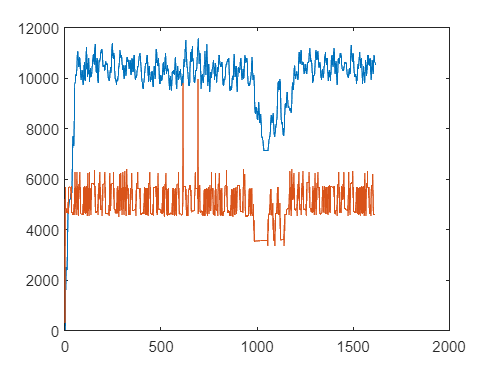

msfile = fopen('received_data.txt','r');

formatSpec = ['%d'];

msdata = fscanf(msfile,formatSpec, [1 inf]);
msdata = msdata/4;

tdiskret = 1/10E6;
tprescaler = 1;

kauke = [ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(2E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

y = GenerateConv(msdata, kauke);

plot(y)
hold on
plot(msdata*10)
hold off

function y = GenerateConv(a, b) % a - pgarindinis
    pilnasSig = [zeros(1, length(b)), a];
    naujas = [];
    for i = length(b):length(pilnasSig)
        sudaugintas = sum(b.*pilnasSig(i-length(b)+1:i));
        naujas = [naujas, sudaugintas];
    end
    y = naujas();
    %{
    y = zeros(1, length(a));
    for i = 1:length(a)-length(b)
        if(i < length(b))
            testArr = [b(1:i), zeros(1, length(a)- i)];
        else
            testArr = [zeros(1, i), b, zeros(1, length(a)-length(b) - i)];
        end
        length(testArr);
        y(i) = sum(a.*testArr);
    end
    %}
end